## **环境交互测试实验2：无人机强化学习路径规划**

%% 添加必要的路径
run('path_add.m')
clear,clc

% 加载数据
filename = "Forest_data.mat";
% 使用exist函数检查文件是否存在  
if exist(filename, 'file') == 2  
    load Forest_environment\Forest_data.mat 
else  
    run("Forest_environment\Forest_generate.m")
    load Forest_environment\Forest_data.mat
end

## 利用快速深度强化学习算法设计无人机路径规划

% 得到待侦察目标位置,以树的顶端作为搜索目标
nodes_target = [selectedNumbers_firepoint,selectedNumbers_burn];
points_target = information_tree(nodes_target,1:3);
for i=1:length(nodes_target)
    points_target(i,3) = points_target(i,3)+trees(nodes_target(i)).height;
end

% 加载一个无人机
max_speed = 100;
max_range = 60;
max_altitude = 310;
max_power = 5000;
max_load = 25;
k_up = 0.05;
k_down = 0.01;
k_around = 0.03;
dt = 0.1;
uav_0 = uav(max_speed,max_range,max_altitude,max_power,max_load,k_up,k_down,k_around,dt);
uav_0 = uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);

% 快速强化学习过程
target = points_target(1,:);
num_prelearn = 200;
numtofly = 50;
[uav_0,agent,distance_ave,min_distance] = Rapid_PP_TPP_RapidDL(uav_0,target,num_prelearn,numtofly,field_tree,trees);

预训练过程结束


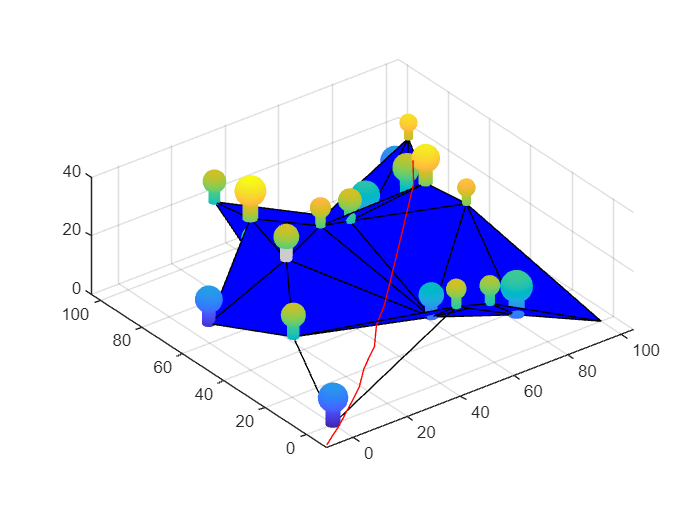

% 让我们将环境和轨迹简单的画出来吧
figure
hold on
draw_trees(trees, field_tree)
plot3(uav_0.position(:,1),uav_0.position(:,2),uav_0.position(:,3),'red')
hold off

pathLength = calculatePathLength(uav_0.position);

% 紧接着我们设计算法，完成对所有目标的路径规划
% 加载一些无人机
max_speed = 200;
max_range = 60;
max_altitude = 310;
max_power = 5000;
max_load = 25;
k_up = 0.05;
k_down = 0.01;
k_around = 0.03;
dt = 0.1;
uav_0 = uav(max_speed,max_range,max_altitude,max_power,max_load,k_up,k_down,k_around,dt);
uavs = [];
for i=1:size(points_target, 1)
    temp_uav = uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);
    uavs = [uavs;temp_uav];
end

% 快速强化学习过程
num_prelearn = 200;
numtofly = 50;
agents = [];
distance_randomcho = [];
distance_agent = [];
for i=1:size(points_target, 1)
    target = points_target(i,:);
    [uavs(i),agent,distance_ave,min_distance] = Rapid_PP_TPP_RapidDL(uavs(i),target,num_prelearn,numtofly,field_tree,trees);
    agents = [agents;agent];
    distance_randomcho = [distance_randomcho;distance_ave];
    temp_pathLength = calculatePathLength(uavs(i).position);
    distance_agent = [distance_agent;temp_pathLength];
end

预训练过程结束


预训练过程结束


预训练过程结束


  219.2426   57.2324   21.3277



预训练过程结束


预训练过程结束


save Env_test_Data\T2_data_train.mat distance_agent distance_randomcho agents uavs

load Env_test_Data\T2_data_train.mat

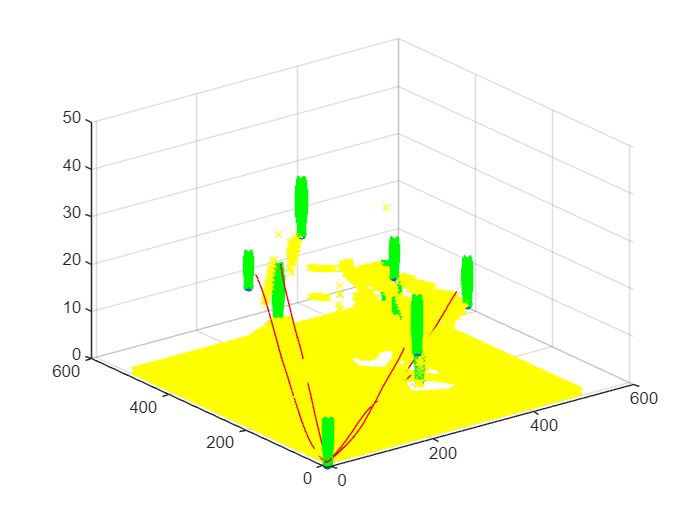

% 让我们将环境和轨迹简单的画出来吧
figure(1)
scatter3(information_tree(:,1),information_tree(:,2),information_tree(:,3),'filled','o')
hold on
scatter3(points(:,1),points(:,2),points(:,3),'green','x')
scatter3(points_field(:,1),points_field(:,2),points_field(:,3),'yellow','x')
for i=1:length(uavs)
    plot3(uavs(i).position(:,1),uavs(i).position(:,2),uavs(i).position(:,3),'red')
end
hold off